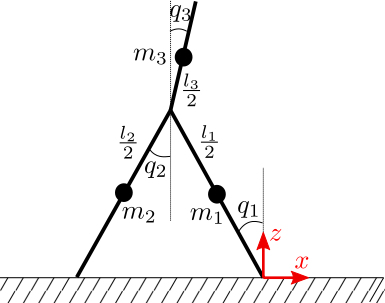

clear
syms x1 z1 x2 z2 x3 z3;
syms dx1 dz1 dx2 dz2 dx3 dz3;
syms q1 q2 q3;
syms dq1 dq2 dq3;
syms l1 l2 l3;

% write the symbolic formulas for x, z of masses m1, m2, m3:
x1 = l1 / 2 * sin(q1);
z1 = l1 / 2 * cos(q1);

x2 = l1 * sin(q1) - l2 / 2 * sin(q2);
z2 = l1 * cos(q1) - l2 / 2 * cos(q2);

x3 = l1 * sin(q1) + l3 / 2 * sin(q3);
z3 = l1 * cos(q1) + l3 / 2 * cos(q3);

% compute velocity of m1 m2 m3
dx1 = diff(x1, q1) * dq1

$$dx1 = \frac{{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)}{2}$$

dz1 = diff(z1, q1) * dq1

$$dz1 = -\frac{{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)}{2}$$


dx2 = diff(x2, q1) * dq1 + diff(x2, q2) * dq2

$$dx2 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}$$

dz2 = diff(z2, q1) * dq1 + diff(z2, q2) * dq2

$$dz2 = \frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}-{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$


dx3 = diff(x3, q1) * dq1 + diff(x3, q3) * dq3

$$dx3 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}$$

dz3 = diff(z3, q1) * dq1 + diff(z3, q3) * dq3

$$dz3 = -{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)-\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}$$

## Some points position for visulization and footstep

% hip
x_h = l1 * sin(q1)

$$x\_h = l_{1}\,\sin\left(q_{1}\right)$$

z_h = l1 * cos(q1)

$$z\_h = l_{1}\,\cos\left(q_{1}\right)$$


% swing foot position
x_swf = l1 * sin(q1) - l2 * sin(q2)

$$x\_swf = l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{2}\right)$$

z_swf = l1 * cos(q1) - l2 * cos(q2)

$$z\_swf = l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)$$


% torso top
x_t = l1 * sin(q1) + l3 * sin(q3)

$$x\_t = l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{3}\right)$$

z_t = l1 * cos(q1) + l3 * cos(q3)

$$z\_t = l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{3}\right)$$


% velocity
dx_h = diff(x_h, q1) * dq1

$$dx\_h = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)$$

dz_h = diff(z_h, q1) * dq1

$$dz\_h = -{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$


dx_swf = diff(x_swf, q1) * dq1 + diff(x_swf, q2) * dq2

$$dx\_swf = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)$$

dz_swf = diff(z_swf, q1) * dq1 + diff(z_swf, q2) * dq2

$$dz\_swf = {\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$

## write a tmp file

% tmp = fopen('tmp.txt', 'wt');
% fprintf(tmp, '%s = %s;\n', 'x1', char(x1));
% fprintf(tmp, '%s = %s;\n', 'z1', char(z1));
% fprintf(tmp, '%s = %s;\n', 'x2', char(x2));
% fprintf(tmp, '%s = %s;\n', 'z2', char(z2));
% fprintf(tmp, '%s = %s;\n', 'x3', char(x3));
% fprintf(tmp, '%s = %s;\n', 'z3', char(z3));
% fprintf(tmp, '%s = %s;\n', 'x_h', char(x_h));
% fprintf(tmp, '%s = %s;\n', 'z_h', char(z_h));
% fprintf(tmp, '%s = %s;\n', 'x_t', char(x_t));
% fprintf(tmp, '%s = %s;\n', 'z_t', char(z_t));
% fprintf(tmp, '%s = %s;\n', 'x_swf', char(x_swf));
% fprintf(tmp, '%s = %s;\n', 'z_swf', char(z_swf));
% fclose(tmp);